# Locally Weighted Scatterplot Smoothing

A program which is developed based on lowess approach for smoothing rate-normalized pressure (RNP) data.

Author: Munthe, Felix A.

Created on Monday, 30 October 2073

## Import Data

### True RNP Data

clear; clc; clf;
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
true_RNP = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\true_RNP.txt", opts)

true_RNP = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


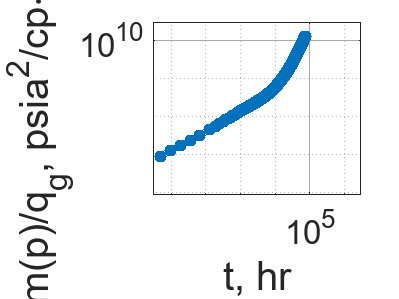


% Plot
loglog(true_RNP.t, true_RNP.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("True RNP Data", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

### Noisy RNP Data Set 207

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
noisy_RNP_207 = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\Noisy RNP Model\All\75%\noisy_data_7.txt", opts)

noisy_RNP_207 = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.2175e+07
    0.33041    1.4013e+08
     0.4862    2.1612e+08
    0.79777    2.5356e+07
     1.4209    2.5764e+08
     2.6672    2.3723e+08
     5.0773    8.8236e+06
     9.8974    1.7648e+08
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    1.2686e+08
     124.99    2.6413e+08
     188.99     2.219e+08
     252.99    3.1122e+08
     316.99    2.1312e+07
     380.99    2.2352e+07


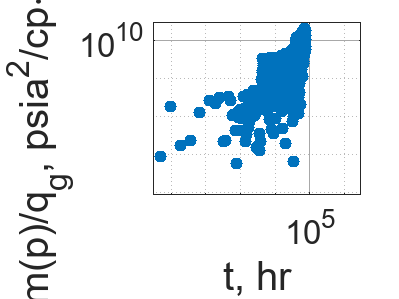


% Plot
loglog(noisy_RNP_207.t, noisy_RNP_207.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("Noisy RNP Data Set 207", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

## Smoothing

### Noisy RNP Data 207

logRNP_207 = log(noisy_RNP_207.RNP);

#### Window: 3

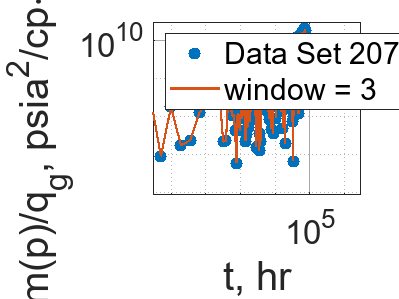

% Plot
loglog(noisy_RNP_207.t, noisy_RNP_207.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 207");
% title("Noisy RNP Data Set 207", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_207_31 = smooth(logRNP_207, 3, "lowess");
smoothedRNP_207_31 = exp(smoothedLogRNP_207_31);
residual_207_31 = (true_RNP.RNP - smoothedRNP_207_31) ./ (0.3413 .* true_RNP.RNP);
sse_207_31 = sum(residual_207_31 .^ 2);
loglog(noisy_RNP_207.t, smoothedRNP_207_31, "-", "LineWidth", 1.3, "DisplayName", "window = 3");
legend("Location", "northwest");
hold off;

### Window: 5

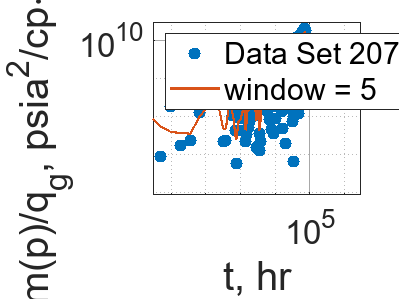

% Plot
loglog(noisy_RNP_207.t, noisy_RNP_207.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 207");
% title("Noisy RNP Data Set 207", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_207_51 = smooth(logRNP_207, 5, "lowess");
smoothedRNP_207_51 = exp(smoothedLogRNP_207_51);
residual_207_51 = (true_RNP.RNP - smoothedRNP_207_51) ./ (0.3413 .* true_RNP.RNP);
sse_207_51 = sum(residual_207_51 .^ 2);
loglog(noisy_RNP_207.t, smoothedRNP_207_51, "-", "LineWidth", 1.3, "DisplayName", "window = 5");
legend("Location", "northwest");
hold off;

#### Window: 7

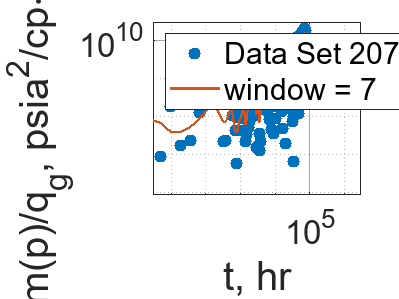

% Plot
loglog(noisy_RNP_207.t, noisy_RNP_207.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 207");
% title("Noisy RNP Data Set 207", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_207_71 = smooth(logRNP_207, 7, "lowess");
smoothedRNP_207_71 = exp(smoothedLogRNP_207_71);
residual_207_71 = (true_RNP.RNP - smoothedRNP_207_71) ./ (0.3413 .* true_RNP.RNP);
sse_207_71 = sum(residual_207_71 .^ 2);
loglog(noisy_RNP_207.t, smoothedRNP_207_71, "-", "LineWidth", 1.3, "DisplayName", "window = 7");
legend("Location", "northwest");
hold off;

#### Window: 9

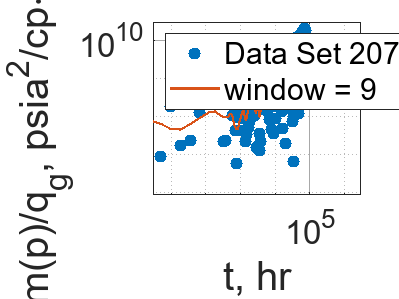

% Plot
loglog(noisy_RNP_207.t, noisy_RNP_207.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 207");
% title("Noisy RNP Data Set 207", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_207_91 = smooth(logRNP_207, 9, "lowess");
smoothedRNP_207_91 = exp(smoothedLogRNP_207_91);
residual_207_91 = (true_RNP.RNP - smoothedRNP_207_91) ./ (0.3413 .* true_RNP.RNP);
sse_207_91 = sum(residual_207_91 .^ 2);
loglog(noisy_RNP_207.t, smoothedRNP_207_91, "-", "LineWidth", 1.3, "DisplayName", "window = 9");
legend("Location", "northwest");
hold off;

#### Window: 11

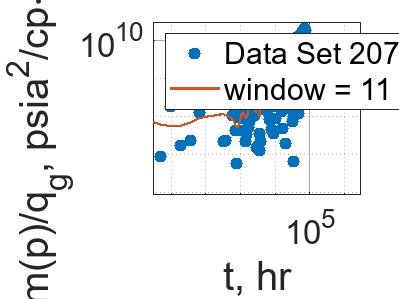

% Plot
loglog(noisy_RNP_207.t, noisy_RNP_207.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 207");
% title("Noisy RNP Data Set 207", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_207_111 = smooth(logRNP_207, 11, "lowess");
smoothedRNP_207_111 = exp(smoothedLogRNP_207_111);
residual_207_111 = (true_RNP.RNP - smoothedRNP_207_111) ./ (0.3413 .* true_RNP.RNP);
sse_207_111 = sum(residual_207_111 .^ 2);
loglog(noisy_RNP_207.t, smoothedRNP_207_111, "-", "LineWidth", 1.3, "DisplayName", "window = 11");
legend("Location", "northwest");
hold off;

#### Window: 13

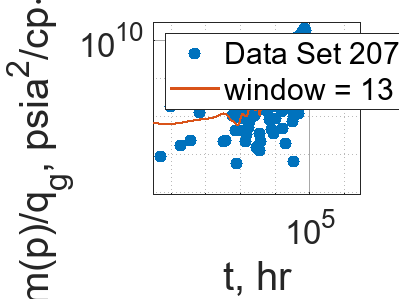

% Plot
loglog(noisy_RNP_207.t, noisy_RNP_207.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 207");
% title("Noisy RNP Data Set 207", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_207_131 = smooth(logRNP_207, 13, "lowess");
smoothedRNP_207_131 = exp(smoothedLogRNP_207_131);
residual_207_131 = (true_RNP.RNP - smoothedRNP_207_131) ./ (0.3413 .* true_RNP.RNP);
sse_207_131 = sum(residual_207_131 .^ 2);
loglog(noisy_RNP_207.t, smoothedRNP_207_131, "-", "LineWidth", 1.3, "DisplayName", "window = 13");
legend("Location", "northwest");
hold off;

#### Window: 15

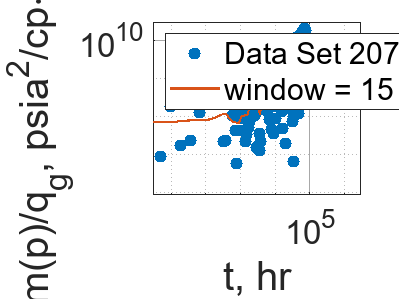

% Plot
loglog(noisy_RNP_207.t, noisy_RNP_207.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 207");
% title("Noisy RNP Data Set 207", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_207_151 = smooth(logRNP_207, 15, "lowess");
smoothedRNP_207_151 = exp(smoothedLogRNP_207_151);
residual_207_151 = (true_RNP.RNP - smoothedRNP_207_151) ./ (0.3413 .* true_RNP.RNP);
sse_207_151 = sum(residual_207_151 .^ 2);
loglog(noisy_RNP_207.t, smoothedRNP_207_151, "-", "LineWidth", 1.3, "DisplayName", "window = 15");
legend("Location", "northwest");
hold off;

#### Window: 17

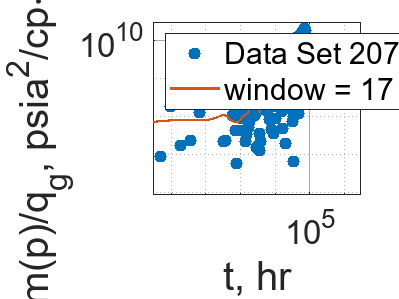

% Plot
loglog(noisy_RNP_207.t, noisy_RNP_207.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 207");
% title("Noisy RNP Data Set 207", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_207_171 = smooth(logRNP_207, 17, "lowess");
smoothedRNP_207_171 = exp(smoothedLogRNP_207_171);
residual_207_171 = (true_RNP.RNP - smoothedRNP_207_171) ./ (0.3413 .* true_RNP.RNP);
sse_207_171 = sum(residual_207_171 .^ 2);
loglog(noisy_RNP_207.t, smoothedRNP_207_171, "-", "LineWidth", 1.3, "DisplayName", "window = 17");
legend("Location", "northwest");
hold off;

#### Window: 19

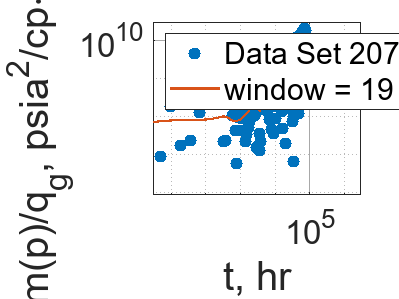

% Plot
loglog(noisy_RNP_207.t, noisy_RNP_207.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 207");
% title("Noisy RNP Data Set 207", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

smoothedLogRNP_207_207 = smooth(logRNP_207, 19, "lowess");
smoothedRNP_207_207 = exp(smoothedLogRNP_207_207);
residual_207_207 = (true_RNP.RNP - smoothedRNP_207_207) ./ (0.3413 .* true_RNP.RNP);
sse_207_207 = sum(residual_207_207 .^ 2);
loglog(noisy_RNP_207.t, smoothedRNP_207_207, "-", "LineWidth", 1.3, "DisplayName", "window = 19");
legend("Location", "northwest");
hold off;